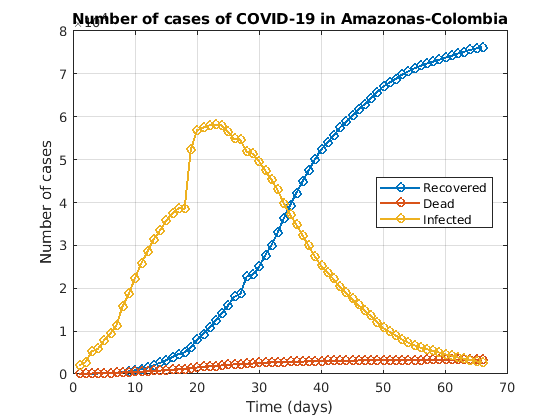

load('../Data/China.mat')
ydata = [Cases-Recovered-Dead;Recovered; Dead];

% ydata = ydata(:, 10:end)';
% ydata = [ydata(2,430:end-15); ydata(3,430:end-15); ydata(1,430:end-15)];
ydata = [ydata(2,5:70); ydata(3,5:70); ydata(1,5:70)];

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

clf
plot(ydata', '-o', 'LineWidth',1.5)
title('Number of cases of COVID-19 in Amazonas-Colombia')
ylabel('Number of cases')
xlabel('Time (days)')
grid on
legend({'Recovered','Dead','Infected'},"Location","best")

# **New expression**

**Create the model as a table for GSUA-CSB toolbox implementation **

First, define the model as a symbolic structure

syms S(t) I(t) R(t) D(t) A(t) E(t) Q(t) C(t)
syms alpha beta delta sigma eta tau epsilon mu gamma k lambda nu z

N = S + C + E + A + I + Q + R + D;

aleph = 1+nu*(I+A)/(I+A+S)

$$aleph(t) = \frac{\nu \,\left(A\left(t\right)+\text{I}\left(t\right)\right)}{A\left(t\right)+\text{I}\left(t\right)+S\left(t\right)}+1$$


P1 = 1-(1 - (I/N)^aleph)^z;
P2 = 1-(1 - (A/N)^aleph)^z;
% P = 1-((S-1)/S)^(z*(I+A)*S/N);

ode1 = diff(S) == -alpha*S - beta*P1*S - sigma*S*P2 - eta*S;
ode2 = diff(A) ==  -tau*A + epsilon*E;
ode3 = diff(C) == alpha*S - mu*C;
ode4 = diff(E) == -gamma*E + S*P1*beta + mu*C + eta*S + ...
                    sigma*S*P2 - epsilon*E;
ode5 = diff(I) == tau*A + gamma*E - delta*I;
ode6 = diff(R) == lambda*Q;
ode7 = diff(Q) == delta*I - lambda*Q - k*Q;
ode8 = diff(D) == k*Q;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7; ode8];
vars = [R D I S A C E Q];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [  ydata(1,1) ydata(1,1);  %R
            ydata(2,1) ydata(2,1);  %D    
            ydata(3,1) ydata(3,1);  %I
            5.8e5 5.8e7;      %S
            10 20000;               %A
            100 10000;              %C
            10 20000;               %E
            100 200000              %Q
];

Range2 = [  0 2;    %alpha
            0 1;   %beta  
            0 1;    %delta
            0 5;    %epsilon
            0 1;    %eta
            0 1;    %gamma
            0 1;    %k
            0 1;    %lambda
            0 1;    %mu            
            0 2000  %nu 
            0 1;   %sigma    
            0 6;    %tau
            0 30   %z
];  

Range = [Range1; Range2];


Finally, use the gsua_dpmat to create the functional table

outs = [1, 2, 3];
% outs = [3];
[T,~] = gsua_dpmat(odes,vars,[0 length(xdata)],'Model','output',outs,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccccccccccccccc} R\left(t\right) & \text{D}\left(t\right) & \text{I}\left(t\right) & S\left(t\right) & A\left(t\right) & C\left(t\right) & \text{E}\left(t\right) & Q\left(t\right) & \alpha & \beta & \delta & \epsilon & \eta & \gamma & k & \lambda & \mu & \nu & \sigma & \tau & z \end{array}\right)$$

T.Row = [ "S(0)","A(0)", "C(0)", "E(0)", "Q(0)",...
    "\alpha", "\beta", "\delta", "\epsilon", "\eta", "\gamma", "k", ...
    "\lambda", "\mu", "\nu" ,"\sigma", "\tau", "z"];

Solver = 'lsqc';    
Opt = optimoptions('lsqcurvefit','UseParallel', false,'MaxFunctionEvaluations',30000, ...
    'MaxIterations', 3000, 'Display','off');

Define the number of parameter estimations to perform and define the vectors to save the estimated parameters and their respective cost value, i.e., residual.

N = 5;
Residual = zeros(N,1);
Params = zeros(N,18);

% parfor i = 1:N
for i = 1:N
    [T_est, ResTemp] = gsua_pe(T,xdata, ydata(outs,:)','solver',Solver,'N',1,'opt',Opt,'save',false);
    Residual(i) = ResTemp;
    Params(i,:) = T_est.Estlsqc;
end

Sort each set of parameters according to each residual value

[ResidualSorted, idx] = sort(Residual);
EstimatedParams = Params(idx, :);

% save("ResultsCovid/Estimations_new_3outs.mat", "EstimatedParams", "ResidualSorted")

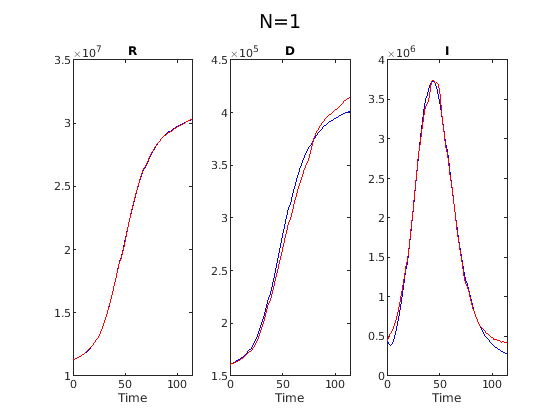

load("ResultsCovid/Estimations_new_3outs.mat")
gsua_eval(EstimatedParams(1,:)', T,xdata, ydata(outs,:));

# Classical expression

**Create the model as a table for GSUA-CSB toolbox implementation**

First, define the model as a symbolic structure

syms S(t) I(t) R(t) D(t) A(t) E(t) Q(t) C(t)
syms alpha beta delta eta tau epsilon mu gamma k lambda nu z sigma

N = S + C + E + A + I + Q + R + D;

ode1 = diff(S) == -alpha*S - beta*I/N*S - sigma*S*A/N - eta*S;
ode2 = diff(A) ==  -tau*A + epsilon*E;
ode3 = diff(C) == alpha*S - mu*C;
ode4 = diff(E) == -gamma*E + beta*I/N*S + mu*C + eta*S + sigma*S*A/N - epsilon*E;
ode5 = diff(I) == tau*A + gamma*E - delta*I;
ode6 = diff(R) == lambda*Q;
ode7 = diff(Q) == delta*I - lambda*Q - k*Q;
ode8 = diff(D) == k*Q;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7; ode8];
vars = [R D I S A C E Q];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [  ydata(1,1) ydata(1,1);  %R
            ydata(2,1) ydata(2,1);  %D    
            ydata(3,1) ydata(3,1);  %I
            143.93e4 143.93e7;      %S
            10 20000;               %A
            100 10000;              %C
            10 20000;               %E
            100 200000              %Q
];

Range2 = [  0 2;    %alpha
            0 10;   %beta  
            0 1;    %delta
            0 5;    %epsilon
            0 1;    %eta
            0 1;    %gamma
            0 1;    %k
            0 1;    %lambda
            0 1;    %mu
            0 10;   %sigma    
            0 6;    %tau
]; 

Range = [Range1; Range2];


Finally, use the gsua_dpmat to create the functional table

outs = [1, 2, 3];
% outs = [3];
[T,~] = gsua_dpmat(odes,vars,[0 length(xdata)],'Model','output',outs,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccccccccccccc} R\left(t\right) & \text{D}\left(t\right) & \text{I}\left(t\right) & S\left(t\right) & A\left(t\right) & C\left(t\right) & \text{E}\left(t\right) & Q\left(t\right) & \alpha & \beta & \delta & \epsilon & \eta & \gamma & k & \lambda & \mu & \sigma & \tau \end{array}\right)$$

T.Row = ["S(0)", "A(0)", "C(0)", "E(0)", "Q(0)",...
    "\alpha", "\beta", "\delta", "\epsilon", "\eta", "\gamma", "k", "\lambda", "\mu", "\sigma",  "\tau"];

Solver = 'lsqc';    
Opt = optimoptions('lsqcurvefit','UseParallel', false,'MaxFunctionEvaluations',30000, ...
    'MaxIterations', 3000, 'Display','off');

Define the number of parameter estimations to perform and define the vectors to save the estimated parameters and their respective cost value, i.e., residual.

N = 100;
Residual = zeros(N,1);
Params = zeros(N,16);

parfor i = 1:N
    [T_est, ResTemp] = gsua_pe(T,xdata, ydata(outs,:),'solver',Solver,'N',1,'opt',Opt,'save',false);
    Residual(i) = ResTemp;
    Params(i,:) = T_est.Estlsqc;
end

Sort each set of parameters according to each residual value

[ResidualSorted, idx] = sort(Residual);
EstimatedParams = Params(idx, :);

save("ResultsCovid/Estimations_class_3outs.mat", "EstimatedParams", "ResidualSorted")

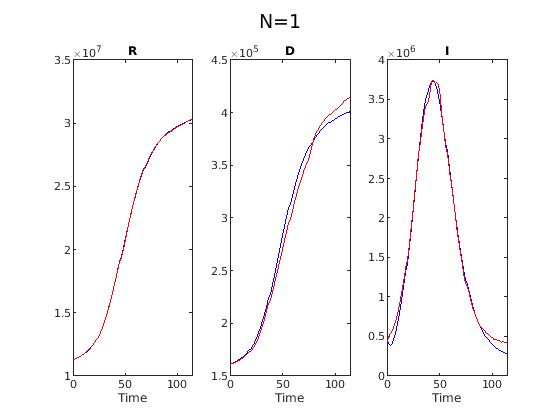

load("ResultsCovid/Estimations_class_3outs.mat")
gsua_eval(EstimatedParams(1,:)', T,xdata, ydata(outs,:));